close all; clear; clc;

# STv4 Steps test 

**file name**: STv4_TM15d_20180809.mlx

**keywords:** settling time, steps test, thrust curves, ramp up and back down

**date of test:** 20180809

**file created by:** 20180813, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** Analyze one battery as external power source. 12 volts, 75 amp hours

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00226591241963588;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_TM15d.mat');
time = STv4_TM15d(:,1);                       % [sec]
PWM = STv4_TM15d(:,2);                        % [micro sec]
Q = STv4_TM15d(:,4);                          % [ft.lbf]
T = STv4_TM15d(:,5);                          % [lbf]
Input_V = STv4_TM15d(:,6);                    % [Volts]
Input_A = STv4_TM15d(:,7);                    % [Amps]
rot_speed_rpm = STv4_TM15d(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv4_TM15d(:,9);                     % [Watts]
P_out_W = STv4_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv4_TM15d(:,11);                 % [%]
Prop_Eff = STv4_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv4_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = STv4_TM15d(:,14);                  % [F]
Motor_Temp = STv4_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

Settling_time = STv4_TM15d(:,17); % [s]
Max_Acc = STv4_TM15d(:,18);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

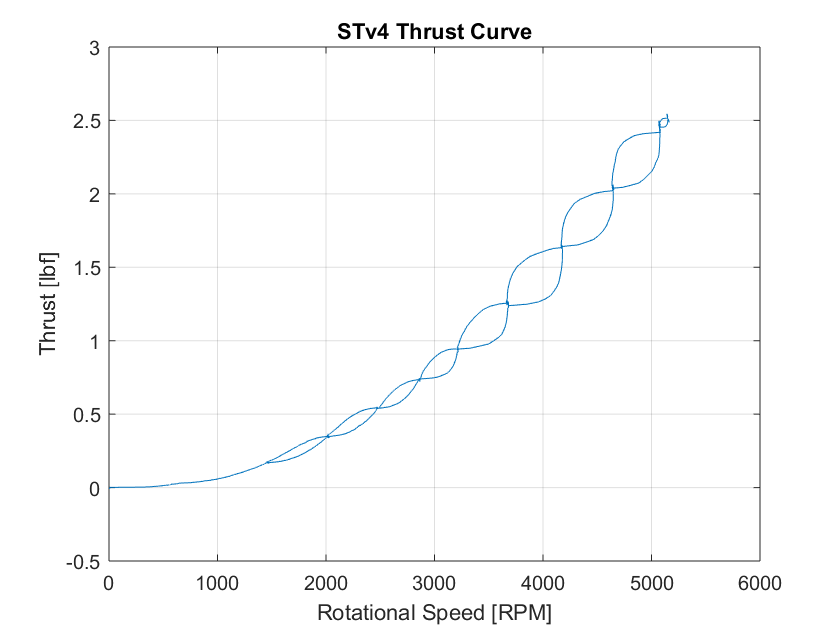

figure(1)
plot(rot_speed_rpm, T); title('STv4 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

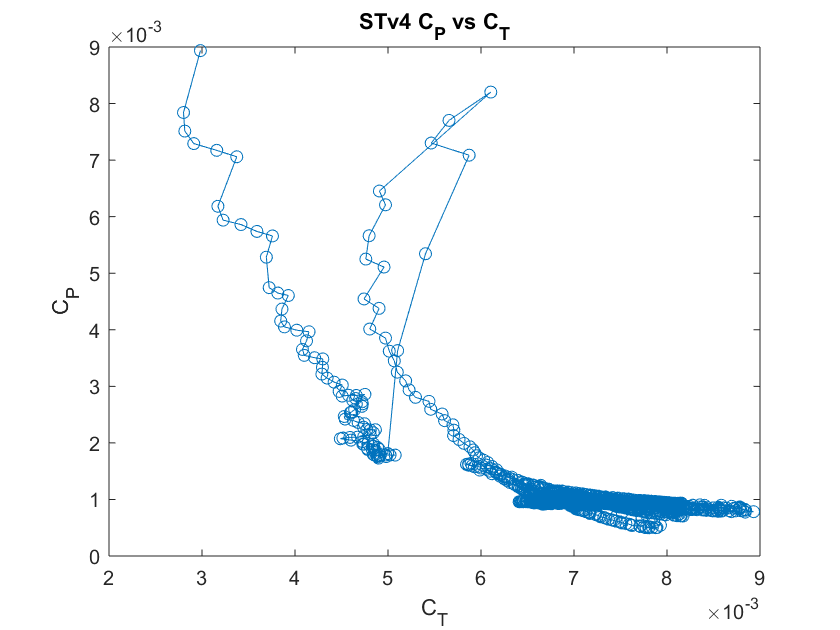


x = (42:14057);

figure(2)
plot(C_T(x), C_P(x),'o-');
title('STv4 C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

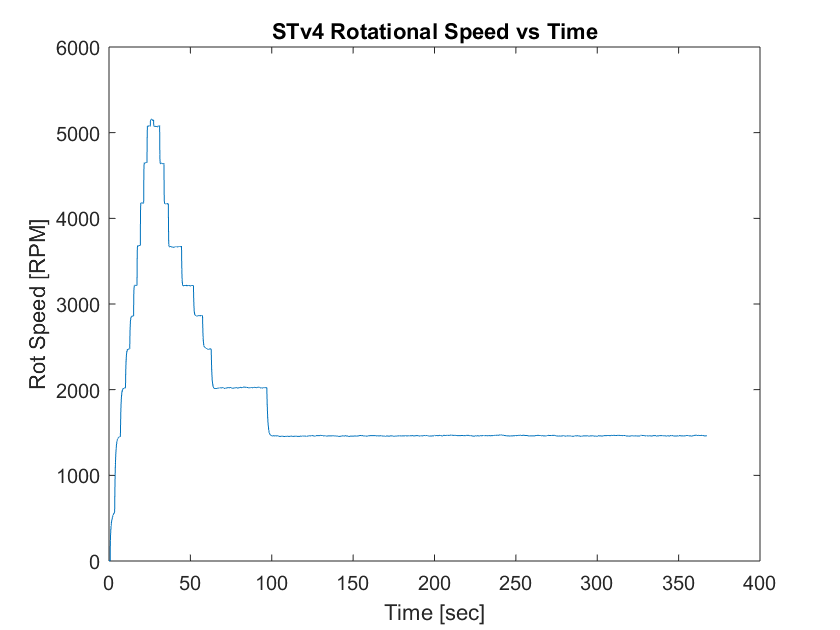


figure(3)
plot(time, rot_speed_rpm); title('STv4 Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

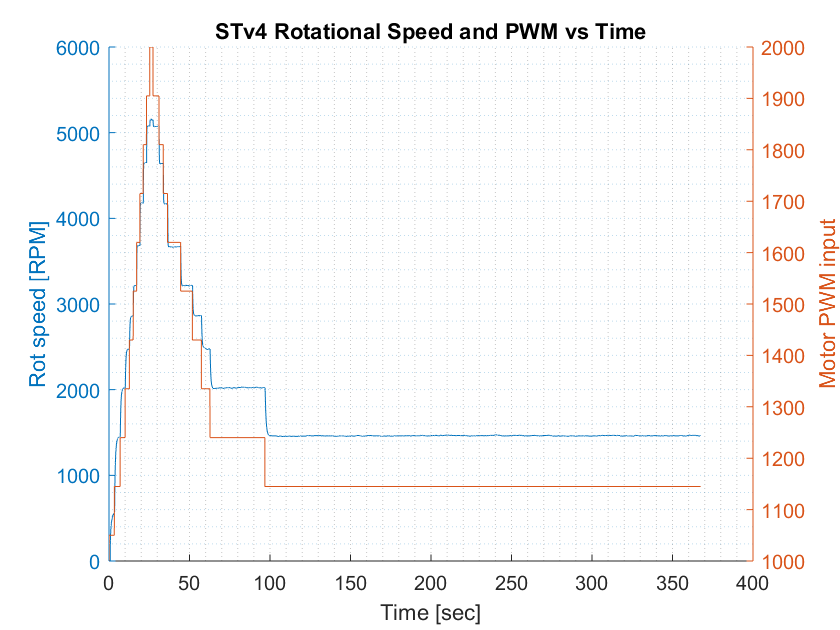


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('STv4 Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

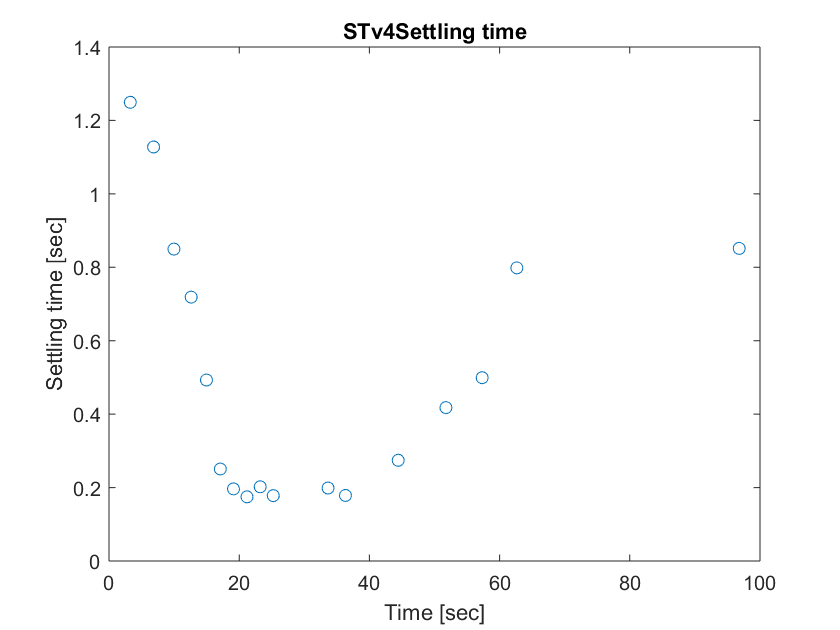



figure(6)
plot(time, Settling_time, 'o-');
title('STv4Settling time'); xlabel('Time [sec]'); ylabel('Settling time [sec]');

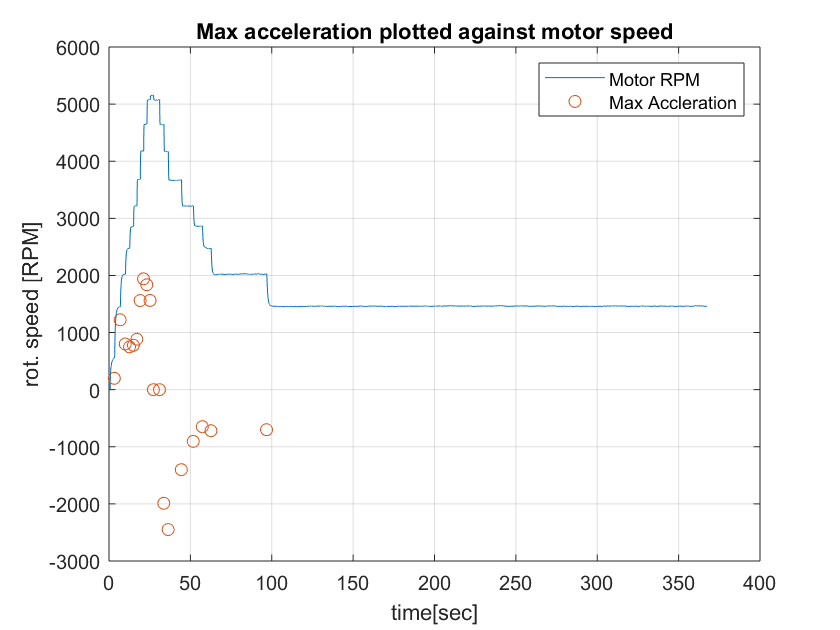


figure(7)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

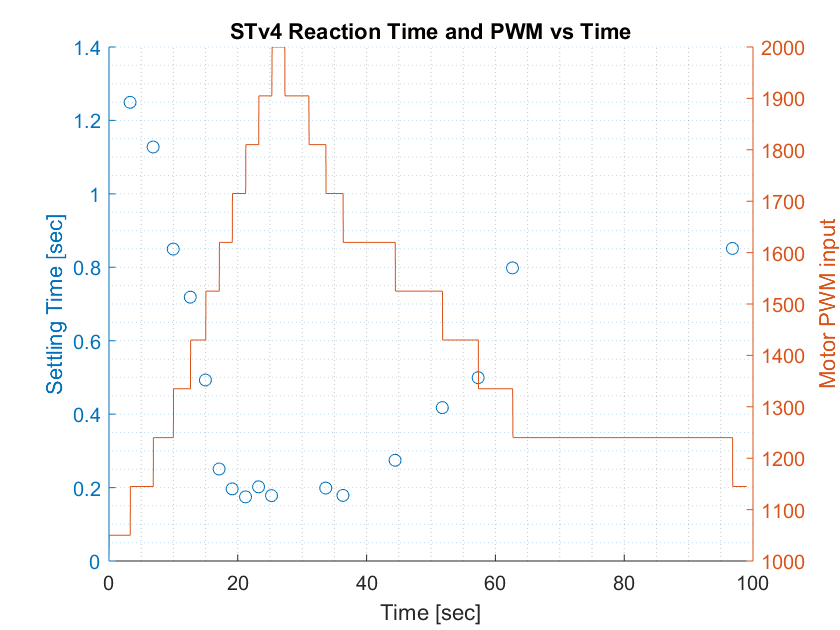


figure(8)
hold on
yyaxis left
plot(time(1:3700),Settling_time(1:3700), 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time(1:3700), PWM(1:3700));
ylabel('Motor PWM input');
title('STv4 Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

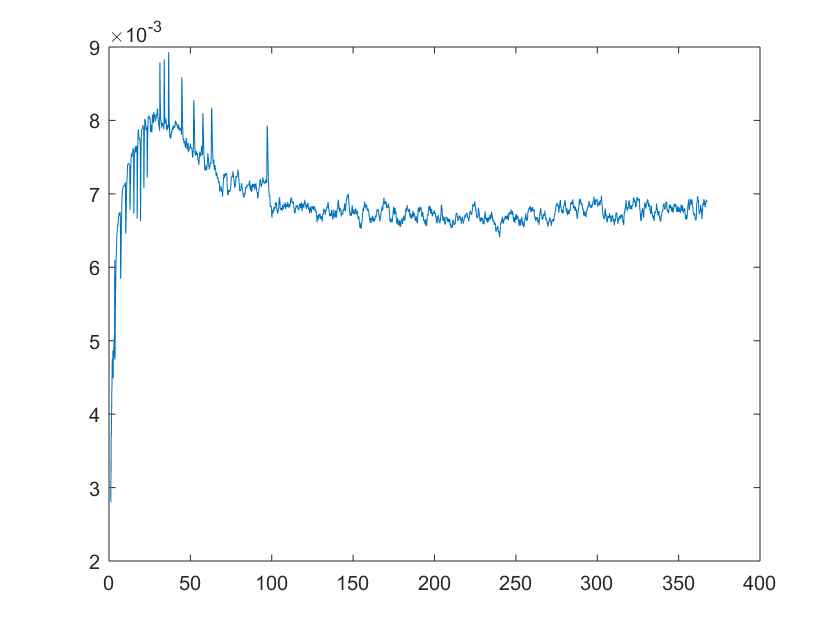


figure(9)
plot(time(x), C_T(x))

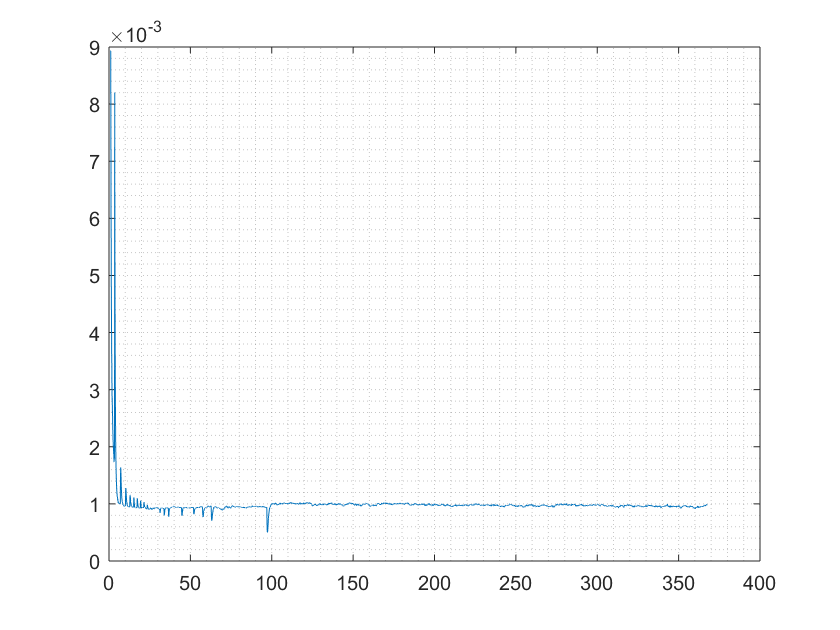



figure(10)
plot(time(x), C_P(x)); grid('minor');

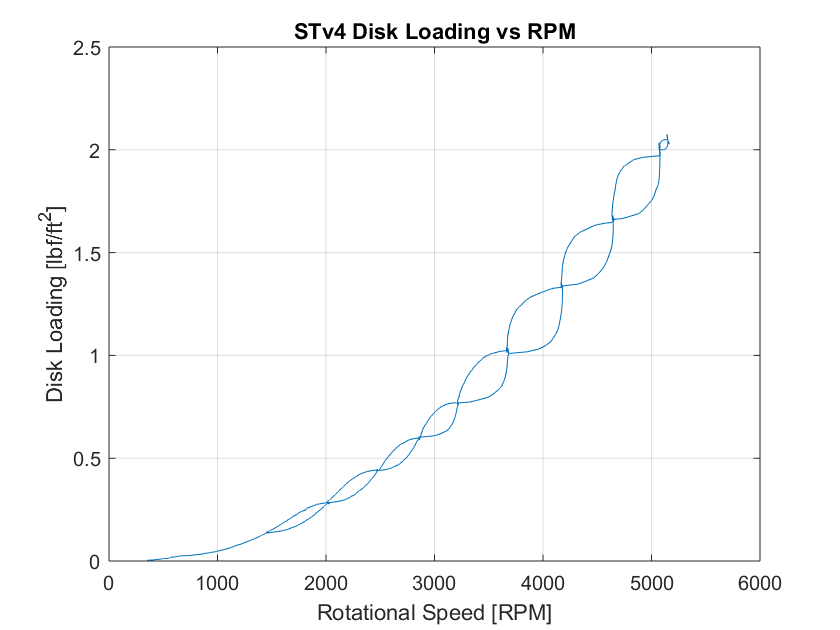



figure(11)
plot(rot_speed_rpm(x), disk_loading(x)); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');